# LAVI walk-through

This script demonstrates how to use LAVI to calculate the rhythmicity profile of a multi-channel dataset, and how to detect the bands. Finally it demonstrates the three possibilities of statistical inference: a. using a pre-computed "look-up table"; b. simulating pink-noise; and c. no statistical inference. 

## Add the LAVI toolbox to your Matlab path

LAVIpath = 'LAVI_folder'; % insert here the location in which the LAVI toolbox is saved
addpath(LAVIpath);

## Load raw data

Data should contain a matrix with N_chan x N_timepoints preprocessed data, and the sampling frequency in Hz.

The script can be tested with the provided 5 minutes rest session of 3 channel EEG.

dataFileName = fullfile(LAVIpath, 'data'); % the path to saved data
load(dataFileName);
%
foi         = 10.^(0.5:0.025:1.65); % frequencies of interest
fsample     = data.fs;              % sampling frequency
lag         = 1.5;                  % lag between the signal and its copy (in cycles, default = 1.5)
width       = 5;                    % wavelet width (in cycles, default = 5)
pink_reps   = 20;                   % number of simulations created per channel. Default = 20.
durs        = 60;                   % the duration (in seconds) of each simulation. Default: the duration of the original signal
choi        = 1:size(data.trial,1); % use this to choose your channels of interest.

## Calculate LAVI of the data

The actual calculation of LAVI is done with the function **Prepare_LAVI**.

It assumes two inputs: cfg (the configuration structure), and the data. Data has to be a matrix (size: channel x timepoints). Can be empty ([]), and then default values are assigned (for default values, see the documantation of Prepare_LAVI). 

The first output is the rhythmicity measure LAVI, as N_channels x N_frequencies.

The second output, cfg, can be used to monitor which default values were assgined by the function.

cfg         = [];
cfg.foi     = foi;
cfg.fs      = fsample;
cfg.lag     = lag;
cfg.width   = width;
cfg.verbose = 1;

dat = data.trial(choi,:); % the original data was saved in a format similar to Fieldtrip. The data matrix is under data.trial
if any(isnan(dat(:))); warning('Data contains NaNs. Calculating TFR by convolution in the time domain'); end
[LAVI,cfg] = Prepare_LAVI(cfg,dat);

Running LAVI frequency 47/47 (44.7 Hz).
The call to Prepare_LAVI took 8.24 seconds


## Plot LAVI

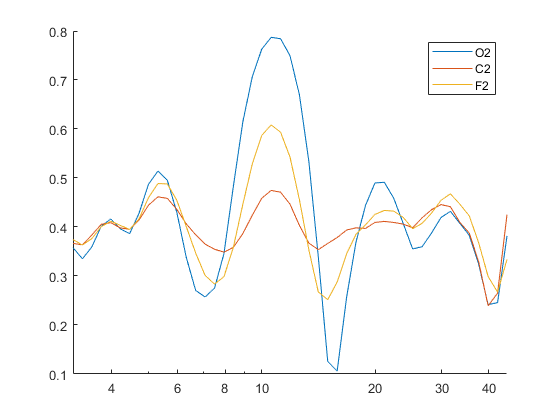

figure(646); clf; hold on
set(gcf,'position',[680 400 560 420]);
plot(foi, LAVI); set(gca,'xscale','log','xtick',[2:2:10,20:10:foi(end)]);
legend(data.label)

## Calculate the borders using ABBA

The function ABBA accepts up to 5 input arguments:

1. **LAVI**: as calculated above by Prepare_LAVI

2. **foi** (frequencies of interest): should be the same as used for calculating LAVI

3. **alpha_range**: the frequency range in which we expact to find alpha. The band of a peak in this range will be assigned the index 0, bands with lower frequency will be assigned with negative indices, and above with positive indices. Default: [6 14]  

4. **sig_lim**: definition of significance levels per frequency. There are three alternatives to define sig_lim:

    a. Using a table based on pre-calculated pink-noise simulations. This table can be generated by the script General_SigLims.m to match data's duration, sampling rate, and aperiodic slope.

    b. Simulating pink-noise that matches the power spectrum of the data.

    c. Leaving empty. In this case, the bands will be found, but without meaningful statistical inference.

For more details, see supplementary text - 'Parametrical effects on rhythmicity measures' and supplementary figure S5 of the original paper.

5. **perFreq**: a boolean defining whether the siginificance level per frequency (1), or as the minimum/ maximum over all frequencies (0, default).

ABBA has 3 possible outputs: 

borders: 1 x Nchan cell array, with a matrix of bands' details per channel (each row is a band, the meaning of columns explained in col_names). 

col_names: 11x1 cell array with the names of variables in the borders matrix. In detail: 1. BegI: the Index of band Beginning 2. EndI: the Index of band Ending 3. PeakI: the Index of band Peak/trough (maximal/ minimal LAVI) 4. BegF: the Frequency of band Beginning 5. EndF: the Frequency of band Ending 6. PeakF: the Frequency of band Peak/trough (maximal/ minimal LAVI) 7. PeakLAVI: the LAVI value at the peak/ trough 8. PeakRel: the difference between PeakLAVI and the median 9. Dir: Direction of the PeakLAVI. 1= Peak ("sustained bands"), -1= Trough ("transient bands"). 10.Rel_alpha: band identity. Alpha= 0. Lower frequency bands get negative integers, Higher frequency positive integers. 11.Sig: bool, Significance relative to pink noise simulations (1- the peak/ trough was higher/ lower than the pink noise distribution, 0 otherwise).

sigVect: 1 x Nchan cell array, with 1 x Nfreq vector per channel of statistical inference per frequency. 

## Option A: use a previously-saved table (much faster compared to option B)

The look-up table is saved under the variable name SIGLIM, which has 5 dimensions: 

1. duration (session dependent) 

2. sampling rate (session dependent) 

3. aperiodic slope ("b", channel dependent) 

4. frequency (should be the same as the foi of LAVI of the original data)

5. min/ max. 

The input to ABBA is an Nfreq x 2 matrix, that is, the last two dimensions relevant to the session/ channel.

alpha_range = [6 14];                           % the peak in LAVI in this range will be considered alpha
siglimFileName = fullfile(LAVIpath, 'SIGLIM');  % the path to saved table of significance levels
load(siglimFileName);                           % the variable name of the look-up table is SIGLIM
siglim = zeros(size(dat,1), size(SIGLIM,4), 2);
dur = data.time(end)-data.time(1);              % session duration is sec
[~,ind1] = min(abs(pmtrSIG.DUR - dur));         % the index of session duration in SIGLIM
[~,ind2] = min(abs(pmtrSIG.FS - data.fs));      % the index sampling frequency in SIGLIM
for ch = 1:size(dat,1)
    [~,b] = get_AP_of_Power(dat(ch,:),data.fs,foi);
    [~,ind3] = min(abs(pmtrSIG.B - b)); % the index aperiodic slope in SIGLIM
    siglim(ch,:,:) = squeeze(SIGLIM(ind1,ind2,ind3,:,:));
end
[borders,col_names,sigVect] = ABBA(LAVI, foi, alpha_range, siglim, 0);

## Option B: Generate pink noise matching the data and calculate its LAVI

Pink noise can be generated with the function computePinkLAVI

cfg             =[];
cfg.Pink_reps   = pink_reps;  % number of repetitions (pink-noise instantiations).
cfg.durs        = durs;       % duration of each simulation, in seconds.
cfg.foi         = foi;        % frequencies of interest. Should match the foi used for the real data.
PINK            = computePinkLAVI(cfg,dat(choi,:)); % dimord: rep_freq_chan

Running PINK ANALYSIS Channel 3/3 repeat 20/20. So far analysis took 16.6 seconds.


% Calculate LAVI of the pink-noise simulations
pink = permute(PINK,[3,2,1]);                    % dimord: chan_freq_rep
sig_lim = cat(3,min(pink,[],3), max(pink,[],3)); % dimord: chan_freq_min/max
alpha_range = [6 14];                            % same as in option A
[borders2,~,sigVect2] = ABBA(LAVI, foi, alpha_range, sig_lim, 0);

## Option C: no meaningful statistical inference

[borders3,~,sigVect3] = ABBA(LAVI, foi, alpha_range);

## Plot LAVI and ABBA

Each channel will be plotted in a separate subplot.

Black: LAVI of original data.  

Pink: LAVI of simulations. 

Green: significantly increased bands.

Blue: significantly decreased bands.

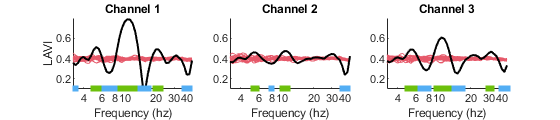

figure(456); clf; hold on
cols   = 3;
rows = ceil(size(LAVI,1)/cols);
set(gcf,'position',[580 480 560 120*rows]);
cachol = [83 174 244]/255; % blue colour
varod  = [230 89 106]/255; % pink colour
yarok  = [108 192 12]/255; % green colour

for chi = 1:size(LAVI,1)
    subplot(rows,cols,chi); hold on
    if exist('PINK')==1 && ~isempty(PINK) % plot pink simulations, only if were generated
        plot(foi, squeeze(PINK(:,:,chi)),'color',ones(1,3)*0.5,'color',varod);
    end
    plot(foi, LAVI(chi,:),'k','linewidth',1.5);
    ylim([0.1 0.8])
    posind = sigVect2{chi}>0;
    negind = sigVect2{chi}<0;
    scatter(foi(posind), ones(1,sum(posind))*0.1,35,yarok,'fill','s');
    scatter(foi(negind), ones(1,sum(negind))*0.1,35,cachol,'fill','s');
    
    set(gca,'xscale','log','xtick',[2:2:10,20:10:foi(end)])
    if mod(chi,cols)==1, ylabel('LAVI'); end
    xlabel('Frequency (hz)')
    title(sprintf('Channel %u',chi))
end